# Create and Customize Waterfall Plots

Waterfall plots are mesh plots with a partial curtain along the y-dimension.

### Create Data

Use `meshgrid` and `findpeaks` in a helper function to generate data for a waterfall plot.

[x,y,z] = createData();

### Basic Waterfall Plot

Plot values in matrix Z as heights above a grid in the xy-plane. The edge color varies by height in the z-direction.

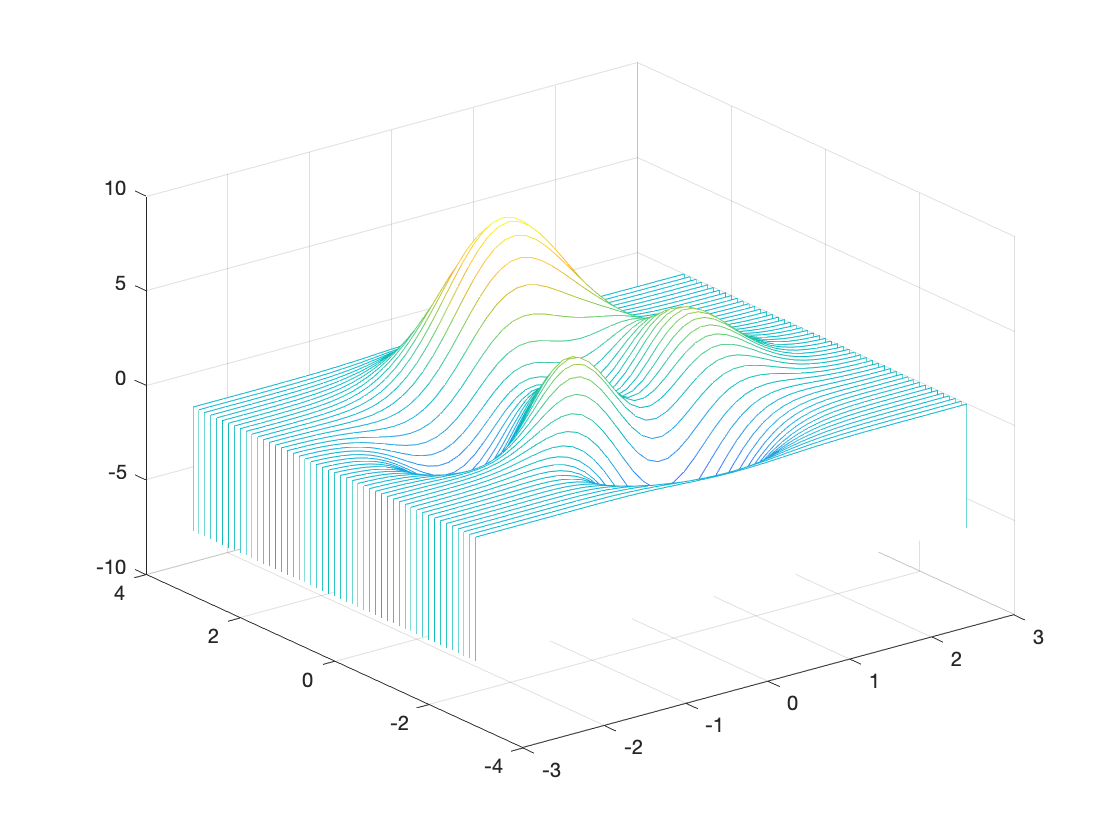

waterfall(x,y,z);

## Customization

### Specify Gradient Color and Add Colorbar

The colors for the gradient and curtain can be specified as the 4th input argument to `waterfall`. Add a colorbar to indicate what gradient the colors represent.

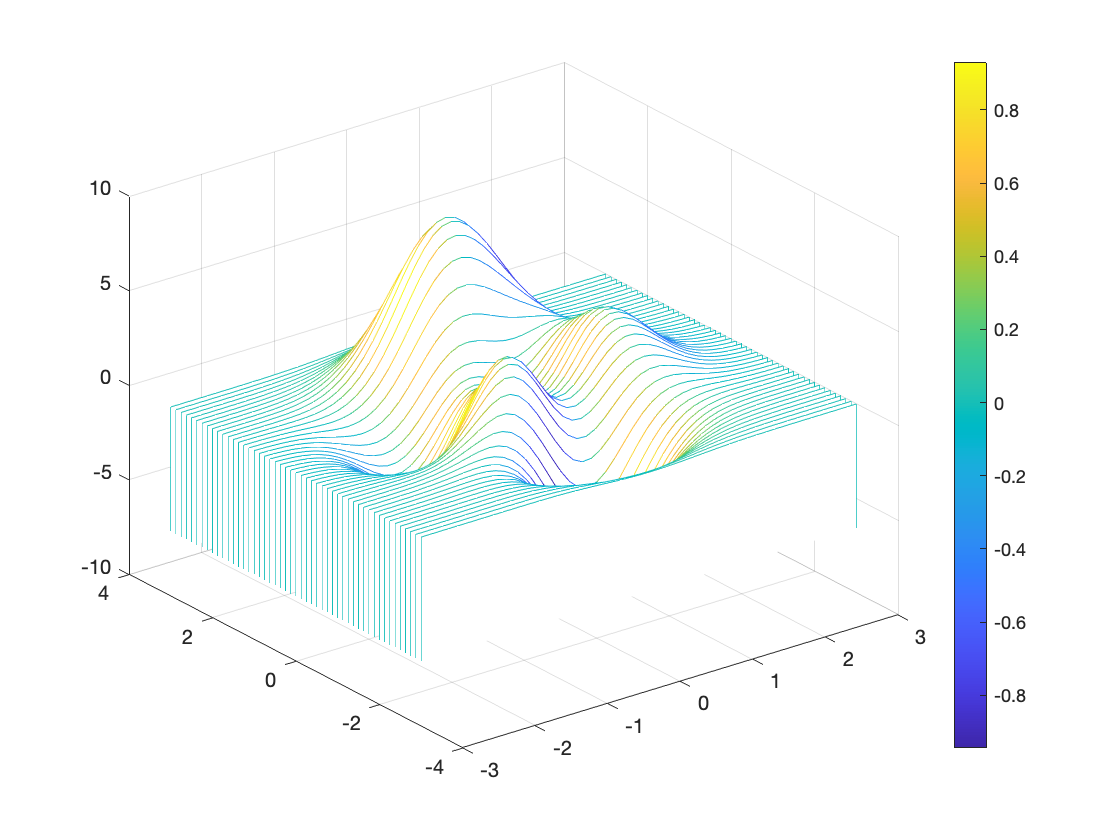

c = gradient(z);
w = waterfall(x,y,z,c); % Specify the gradient as the input that determines mesh color
colorbar

### Change Plot Color

If a uniform plot color is desired, specify the desired plot color as an RGB triplet. Use `repmat` to generate a color vector that can be used to specify the *FaceVertexCData* property. This can be done using a Name, Value pair argument to the `set` function.

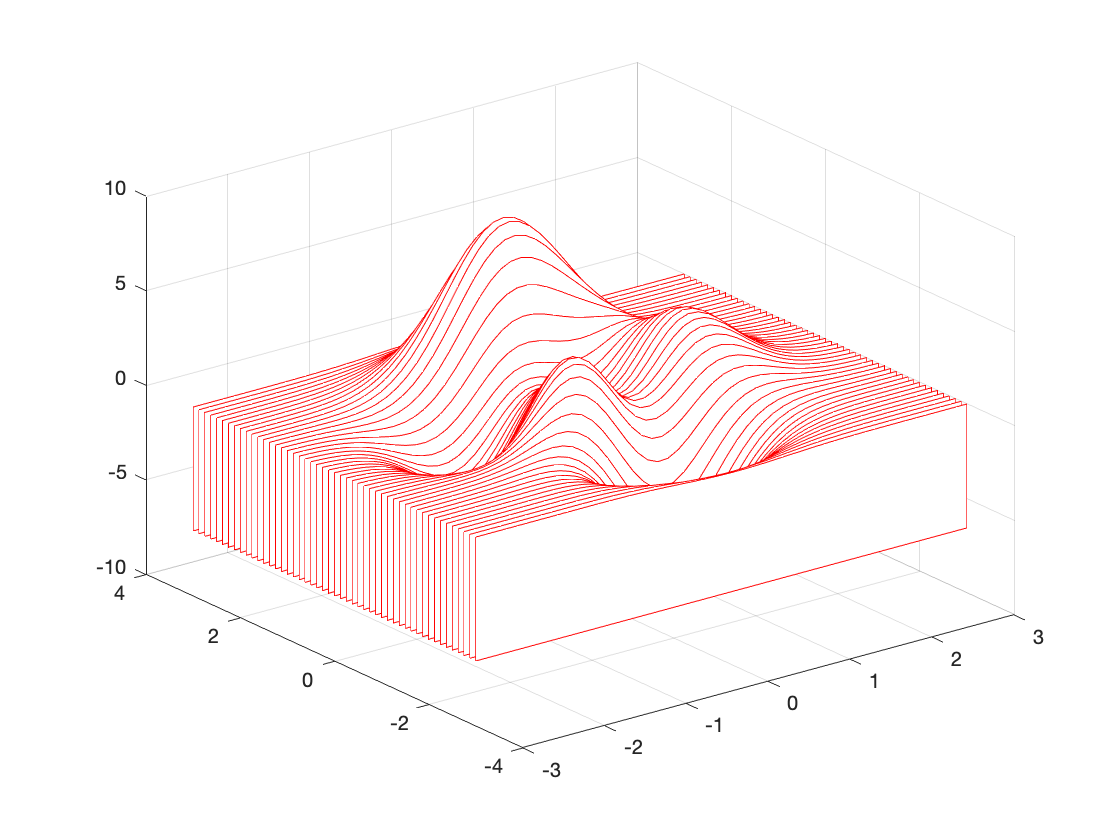

color = [1 0 0];
figure
w1 = waterfall(x,y,z);

colorVec = repmat(color,numel(w1.FaceVertexCData),1);   % Create color vector using repmat
set(w1,...
    "FaceVertexCData",colorVec);                        % Use the patch handle to specify face colors

### Change Chart Colormap and LineWidth

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. The line width of the patch object can modified by accessing the Patch object's *LineWidth* property using dot notation to improve visibility.

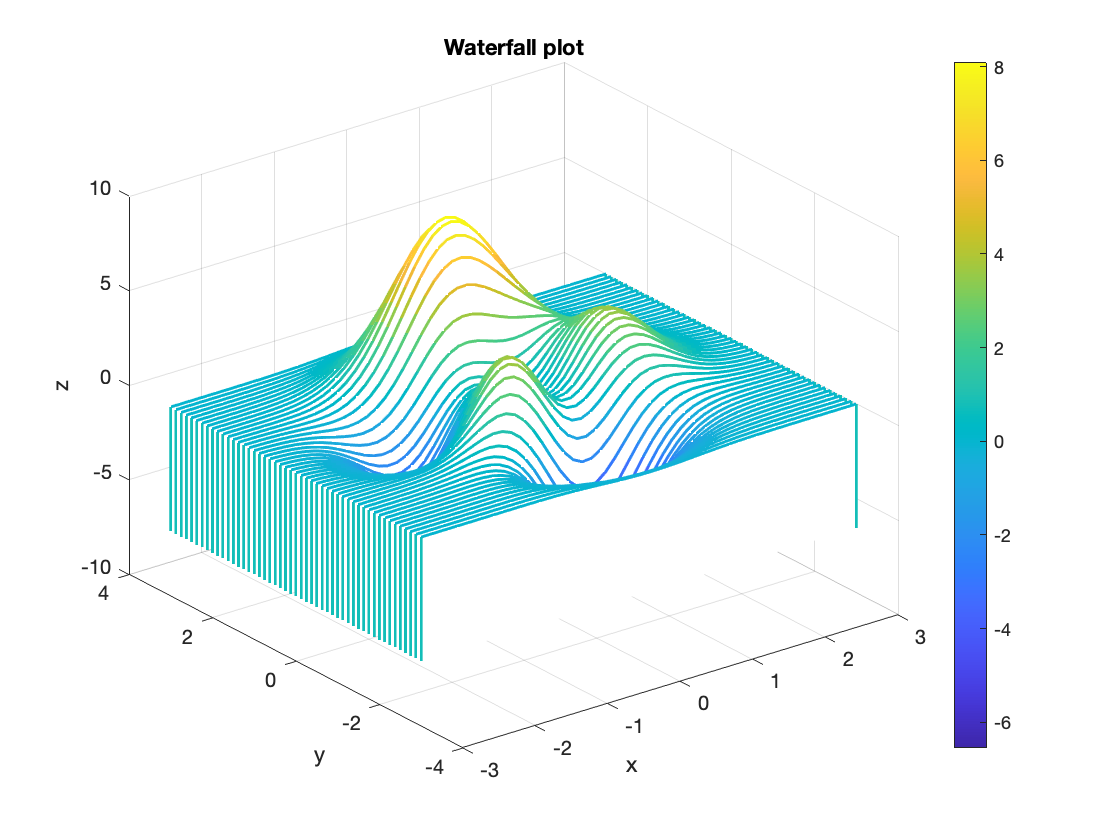

w2 = waterfall(x,y,z);

colormap("parula");             % Specify colormap
w2.LineWidth =1.5;   % Specify line width

colorbar
title("Waterfall plot")
xlabel("x"); ylabel("y"); zlabel("z");

## **Additional Information**

### **Get All Patch Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Patch, uncomment the following code. View or modify these properties using dot notation.

% get(w)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[waterfall](https://www.mathworks.com/help/matlab/ref/waterfall.html)

### Helper Functions

This function generates x,y, and z data using `peaks` and `meshgrid`.

function [x,y,z] = createData()
    [x,y] = meshgrid(-3:.125:3);
    z = peaks(x,y);
end

Copyright (c) 2021, The MathWorks, Inc.